# TSVD-Regularisierung beim Entfaltungsproblem

 Wir betrachten das einem Entfaltungsproblem entsprechende lineare Ausgleichsproblem (siehe Beispiel 4.43 im Buch). 

 Die exakte Lösung $x^\ast$ wird geplottet.

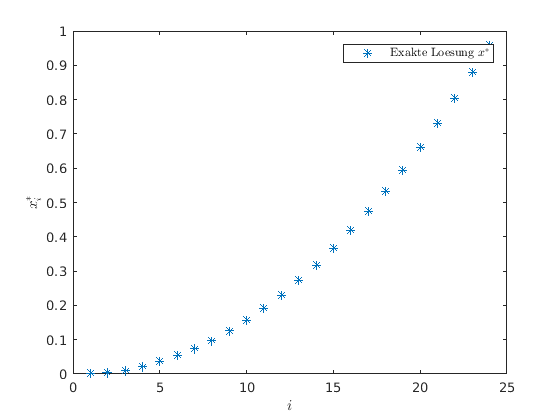

n=24;
h=1/n;
m=50;
ht=1/(m-1);
A=zeros(m,n);
for i=1:m
    for j=1:n
     zj=(j-0.5)*h;
     ti=(i-1)*ht;
 A(i,j)=h*exp(-(zj-ti)^2);
end;
end;
xexakt=zeros(n,1);
b=zeros(m,1);
 for i=1:n
     xexakt(i)=((i-0.5)*h)^2;
 end;
 plot(xexakt,'*');
 leg1=legend('Exakte Loesung $x^\ast$');
 set(leg1,'Interpreter','latex');
 xlabel('$i$','Interpreter','latex'); ylabel('$x_i^\ast$','Interpreter','latex');

 Die "perfekten" Daten werden mit einem normalverteilten Fehler gestört und der relative Datenfehler wird bestimmt:

 b= A*xexakt;
 db= 10^(-2)/sqrt(m)*randn(m,1);
 Datenfehler= norm(db)/norm(b)

Datenfehler = 0.0049

Das gewöhnliche Ausgleichsproblem zu den gestörten Daten $\tilde b=b+\Delta b$

                                  
$$\|A\tilde x - \tilde b\|_2 = \min_{z \in \mathbb R^n} \|Az - \tilde b \|_2$$


 wird gelöst und die Lösung $\tilde x$ geplottet.

xt=A\(b+db);

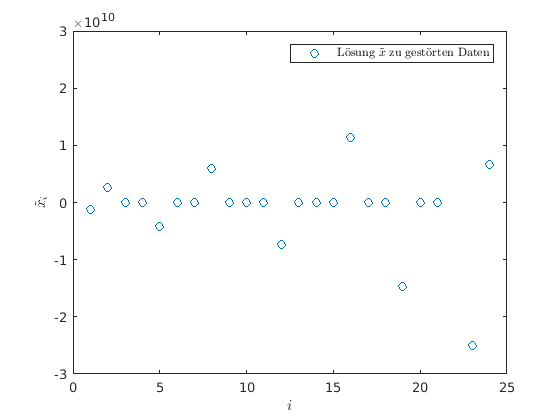

plot(xt,'o');
leg1=legend('L\"osung $\tilde x$ zu gest\"orten Daten');
set(leg1,'Interpreter','latex');
xlabel('$i$','Interpreter','latex'); ylabel('$\tilde x_i$','Interpreter','latex');

Konditionszahl= cond(A)

Konditionszahl = 1.4564e+17

Offensichtlich hat die berechnete Lösung $\tilde x$ nichts mehr mit der exakten Lösung $x$ zu tun. Das lässt sich durch die extrem große Konditionszahl erklären.

Das Problem lässt sich also nur sinnvoll mittels Regularisierung lösen. Wir verwenden hier die TSVD-Regularisierung. Die SVD wird berechnet und die TSVD-Regularisierung angewendet. Die Singulärwerte und die TSVD-Annäherung $\tilde x_\alpha$ werden geplottet. Um eine gute Annäherung zu erhalten, muss der Parameter $\alpha$  geeignet gewählt werden. 

# Aktivität:

Variieren Sie den Parameter $\alpha$.

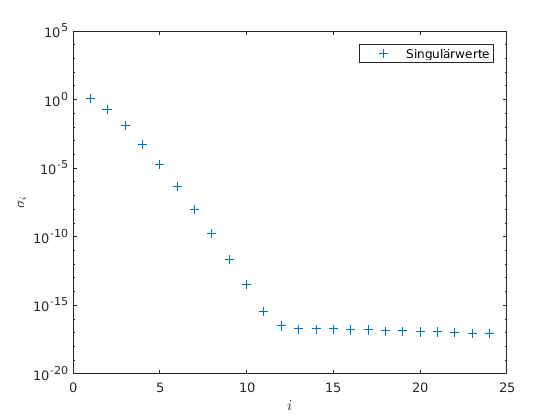

alpha=10^-3;

[U,S,V]=svd(A);
semilogy(diag(S),'+')
legend('Singulärwerte');
xlabel('$i$','Interpreter','latex'); ylabel('$\sigma_i$','Interpreter','latex');

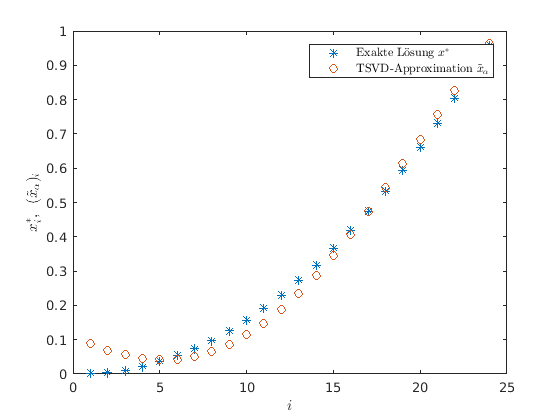

Sreg=zeros(n,m);
for i=1:n
if (abs(S(i,i))> alpha)
    Sreg(i,i)=1/S(i,i);
end;
end;
x_TSVD=V*Sreg*U'*(b+db);
plot(xexakt,'*'); hold on;
plot(x_TSVD,'o');
leg1=legend('Exakte L\"osung $x^\ast$','TSVD-Approximation $\tilde{x}_{\alpha}$');
set(leg1,'Interpreter','latex');
xlabel('$i$','Interpreter','latex'); ylabel('$x_i^\ast$, $~(\tilde x_\alpha)_i$','Interpreter','latex');
hold off